# Twist Boundary Condition 测试


$$H=-t\sum_{m=1}^{N_s-1}\left(c_mc_{m+1}+h.c.\right)-t\left(e^{i\theta}c_{N_s}^\dagger c_1+h.c.\right)$$


[用扭转边界降低晶格模型计算的有限尺寸效应 - 知乎](https://zhuanlan.zhihu.com/p/1899119702296474068)

## 没有采用twist角时的收敛性计算，当$L_x >150$时收敛。

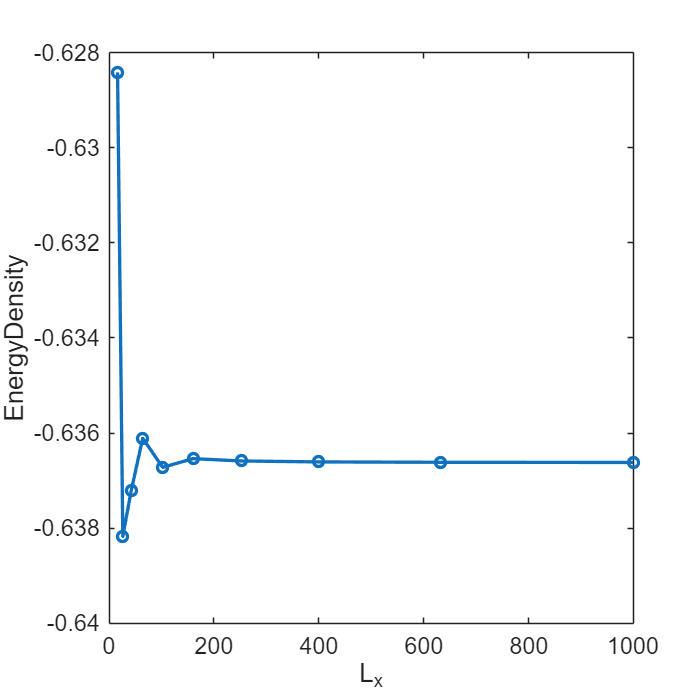

clear;
tic;
Sys_Length = 2*ceil(logspace(log10(8),log10(500),10));
t = 1;
theta = 0;
Energy_Density = zeros(length(Sys_Length), 1);
for ii = 1: length(Sys_Length)
    Len_Loop = Sys_Length(ii);
    H = sparse(-t * diag(ones(Len_Loop-1, 1),1) - t * diag(ones(Len_Loop-1, 1),-1));
    H(1, end) = -t;
    H(end, 1) = -t;
    Ener_Ground = eig(H);
    Energy_Density(ii) = sum(Ener_Ground(Ener_Ground<0)) / Len_Loop;
end

plot(Sys_Length, Energy_Density,'-o','LineWidth',2)
set(gca,'FontSize',14)
set(gca,'linewidth',1)
xlabel('L_x')
ylabel('EnergyDensity')


Converge_Ener_Density = Energy_Density(end);
disp(['Converged Energy Density is ', num2str(Converge_Ener_Density)]);

Converged Energy Density is -0.63662


## 采用twist角时的收敛性计算, 随机选取

### 横坐标为平均次数

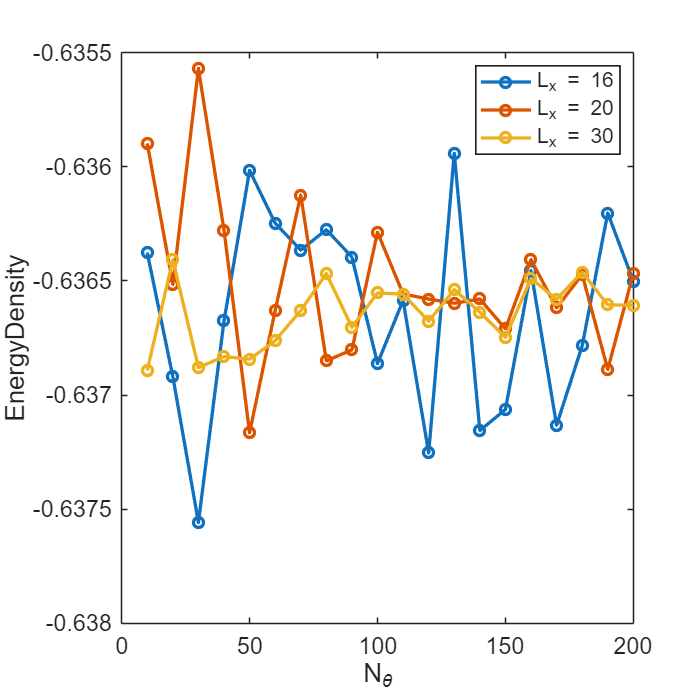

Sys_Length = [16, 20, 30];

ave = 10:10:200;
Energy_Density = zeros(length(Sys_Length), length(ave));
for ii = 1: length(Sys_Length)
    Len_Loop = Sys_Length(ii);
    H = -t * diag(ones(Len_Loop-1, 1),1) - t * diag(ones(Len_Loop-1, 1),-1);
    
    for jj = 1:length(ave)
        temp_Energy = zeros(1, ave(jj));
        for kk = 1:ave(jj)
            phi = 2*pi*rand;
            H(1, end) = -t*exp(-1i * phi);
            H(end, 1) = -t*exp(1i * phi);
            Ener_Ground = eig(H);
            temp_Energy(kk) = sum(Ener_Ground(Ener_Ground<0)) / Len_Loop;
        end
        Energy_Density(ii,jj) = mean(temp_Energy);
    end
end
plot(ave, Energy_Density,'-o','LineWidth',2)
set(gca,'FontSize',14)
set(gca,'linewidth',1)
xlabel('N_\theta')
ylabel('EnergyDensity')

legend(arrayfun(@(x) ['L_x = ',num2str(x)], Sys_Length,'UniformOutput',false))

## 采用twist角时的收敛性计算, 均匀选取

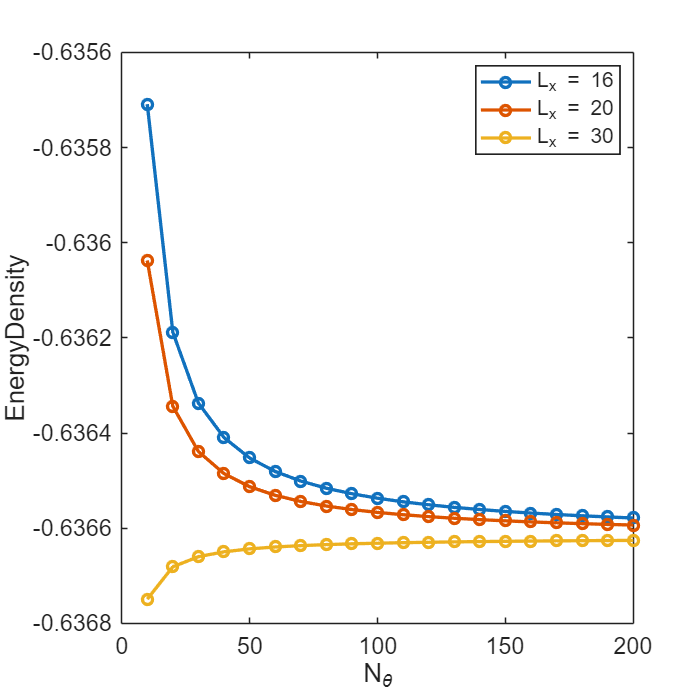

Sys_Length = [16, 20, 30];

ave = 10:10:200;
Energy_Density = zeros(length(Sys_Length), length(ave));
for ii = 1: length(Sys_Length)
    Len_Loop = Sys_Length(ii);
    H = -t * diag(ones(Len_Loop-1, 1),1) - t * diag(ones(Len_Loop-1, 1),-1);
    
    for jj = 1:length(ave)
        temp_Energy = zeros(1, ave(jj));
        phi = 2*pi*linspace(0,1,ave(jj));
        for kk = 1:ave(jj)
            H(1, end) = -t*exp(-1i * phi(kk));
            H(end, 1) = -t*exp(1i * phi(kk));
            Ener_Ground = eig(H);
            temp_Energy(kk) = sum(Ener_Ground(Ener_Ground<0)) / Len_Loop;
        end
        Energy_Density(ii,jj) = mean(temp_Energy);
    end
end
plot(ave, Energy_Density,'-o','LineWidth',2)
set(gca,'FontSize',14)
set(gca,'linewidth',1)
legend(arrayfun(@(x) ['L_x = ',num2str(x)], Sys_Length,'UniformOutput',false))
xlabel('N_\theta')

ylabel('EnergyDensity')

disp(['Converged Energy Density is ', num2str(Energy_Density(end,end))]);

Converged Energy Density is -0.63663


disp(['Compared to non twist case, the difference is ', num2str((Energy_Density(end,end) - Converge_Ener_Density)/Converge_Ener_Density)])

Compared to non twist case, the difference is 1.2486e-05


toc;

历时 1.230258 秒。
